## Production Forecasting for Oil, Water and Gas

### Load Dataset

TrainData = readtable("dseats_2024_training_dataset","TextType","string",VariableNamingRule="preserve")

TrainData = 6925×16 table
    PRODUCTION DATE     Field Name     WELL_BORE_CODE      N_WELL_BORE_CODE    WellBore Name     FLOW_KIND      WELL_TYPE    Downhole Pressure (PSI)    Downhole Temperature (Kelvin)    Average Tubing Pressure    Annulus Pressure (PSI)    AVG WHP (PSI)    Choke Size    Oil Production (stb/day)    Gas Volume (scf/day)    Water Production (stb/day)
    ________________    __________    _________________    ________________    _____________    ____________    _________    _______________________    _____________________________    ________

ValidationData = readtable("dseats_2024_validation_dataset","TextType","string",VariableNamingRule="preserve")

ValidationData = 2075×16 table
      PRODUCTION DATE      Field Name     WELL_BORE_CODE      N_WELL_BORE_CODE    WellBore Name     FLOW_KIND      WELL_TYPE    Downhole Pressure (PSI)    Downhole Temperature (Kelvin)    Average Tubing Pressure    Annulus Pressure (PSI)    AVG WHP (PSI)    Choke Size    Oil Production (stb/day)    Gas Volume (scf/day)    Water Production (stb/day)
    ___________________    __________    _________________    ________________    _____________    ____________    _________    _______________________    _____________________________    

### **Data Preparation**

summary(TrainData)

Variables:

    PRODUCTION DATE: 6925×1 datetime

        Values:

            Min       12/02/2008 00:00
            Median    20/01/2013 00:00
            Max       30/06/2015 00:00

    Field Name: 6925×1 string

    WELL_BORE_CODE: 6925×1 string

    N_WELL_BORE_CODE: 6925×1 double

        Values:

            Min         105   
            Median      107   
            Max         109   

    WellBore Name: 6925×1 string

    FLOW_KIND: 6925×1 string

    WELL_TYPE: 6925×1 string

    Downhole Pressure (PSI): 6925×1 double

        Values:

            Min             0 
            Median     3378.4 
            Max        4606.7 

    Downhole Temperature (Kelvin): 6925×1 double

        Values:

            Min        273.15 
            Median     376.91 
            Max        381.65 

    Average Tubing Pressure


Twell = cell(5,1);
for w = 1:5
    id = TrainData{:,4} == 104+w;
    Twell{w} = TrainData(id,:);
end


Partition Data

Trwell = cell(5,1);
Tewell = cell(5,1);
 for k = 1:5
    n = size(Twell{k},1);
    idTr = 1:floor(0.85*n);
    idTe = floor(0.85*n)+1:n;
    Trwell{k} = Twell{k}(idTr,:);
    Tewell{k} = Twell{k}(idTe,:);
 end


Extract Predictors

 Wellpred = cell(5,1);

 for k = 1:5
    Wellpred{k} = Trwell{k}(1:end,8:16);
 end
 

Clean Data by replacing negative values and NaNs

 for k = 1:5
    id1 = ismissing(Wellpred{k})
    no_missingData = nnz(id1)
    neg = Wellpred{k}{:,:} < 0
    no_negativeData = nnz(neg)

    if no_negativeData > 0

    [idnegr,idnegc] = find(neg)
    mneg = Wellpred{k}{idnegr,idnegc}
    Wellpred{k} = standardizeMissing(Wellpred{k},mneg(:,1))
    Wellpred{k} = fillmissing(Wellpred{k},"constant",0)

    elseif no_missingData > 0
        [idr,idc] = find(id1)
        mmiss = Wellpred{k}(idr,:)
        Wellpred{k} = fillmissing(Wellpred{k},"linear")

    else
     Wellpred{k} = Wellpred{k}
    end
end

id1 = 382×9 logical array
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0


no_missingData = 0

neg = 382×9 logical array
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0


no_negativeData = 0

Wellpred = 5×1 cell array
    { 382×9 table}
    { 612×9 table}
    {2219×9 table}
    {2219×9 table}
    { 453×9 table}


id1 = 612×9 logical array
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   1   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   1   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0


no_missingData = 6

neg = 612×9 logical array
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0


no_negativeData = 0

idr =      3
     5
    16
    19
    20
    23


idc =      6
     6
     6
     6
     6
     6


mmiss = 6×9 table
    Downhole Pressure (PSI)    Downhole Temperature (Kelvin)    Average Tubing Pressure    Annulus Pressure (PSI)    AVG WHP (PSI)    Choke Size    Oil Production (stb/day)    Gas Volume (scf/day)    Water Production (stb/day)
    _______________________    _____________________________    _______________________    ______________________    _____________    __________    ________________________    ____________________    __________________________

               0                          273.15                           0                         0                     0             NaN                      0                           0                     0        

Wellpred = 5×1 cell array
    { 382×9 table}
    { 612×9 table}
    {2219×9 table}
    {2219×9 table}
    { 453×9 table}


id1 = 2219×9 logical array
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0


no_missingData = 0

neg = 2219×9 logical array
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0


no_negativeData = 2

idnegr =           72
        1592


idnegc =      9
     9


mneg = 1.0e+03 *

   -0.0893   -0.0893
   -2.8798   -2.8798


Wellpred = 5×1 cell array
    { 382×9 table}
    { 612×9 table}
    {2219×9 table}
    {2219×9 table}
    { 453×9 table}


Wellpred = 5×1 cell array
    { 382×9 table}
    { 612×9 table}
    {2219×9 table}
    {2219×9 table}
    { 453×9 table}


id1 = 2219×9 logical array
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0


no_missingData = 0

neg = 2219×9 logical array
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0


no_negativeData = 2

idnegr =          384
        1592


idnegc =      9
     9


mneg =    -5.9755   -5.9755
 -372.3051 -372.3051


Wellpred = 5×1 cell array
    { 382×9 table}
    { 612×9 table}
    {2219×9 table}
    {2219×9 table}
    { 453×9 table}


Wellpred = 5×1 cell array
    { 382×9 table}
    { 612×9 table}
    {2219×9 table}
    {2219×9 table}
    { 453×9 table}


id1 = 453×9 logical array
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0


no_missingData = 0

neg = 453×9 logical array
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0


no_negativeData = 0

Wellpred = 5×1 cell array
    { 382×9 table}
    { 612×9 table}
    {2219×9 table}
    {2219×9 table}
    { 453×9 table}


Wellpredf = cell(5,1);
Welltar = cell(5,1);
 for k = 1:5
    Wellpredf{k} = Wellpred{k}(1:end-1,1:9);
    Welltar{k} = Wellpred{k}(2:end,7:9);
 end

Normalize Data

mux = cell(5,1)

mux = 5×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sigx = cell(5,1)

sigx = 5×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


muT = cell(5,1)

muT = 5×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sigT = cell(5,1)

sigT = 5×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


for k = 1:5
 mux{k} = mean(Wellpredf{k})
 sigx{k} = std(Wellpredf{k})

 muT{k} = mean(Welltar{k})
 sigT{k} = std(Welltar{k})

 Wellpredf{k} = (Wellpredf{k} - mux{k}) ./ sigx{k}
 Welltar{k} = (Welltar{k} - muT{k}) ./ sigT{k}

 missing = nnz(ismissing(Wellpredf{k}))
 if missing > 0
    Wellpredf{k} = fillmissing(Wellpredf{k},"constant",0)  
 end
end

mux = 5×1 cell array
    {1×9 table }
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sigx = 5×1 cell array
    {1×9 table }
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


muT = 5×1 cell array
    {1×3 table }
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


sigT = 5×1 cell array
    {1×3 table }
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


Wellpredf = 5×1 cell array
    { 381×9 table}
    { 611×9 table}
    {2218×9 table}
    {2218×9 table}
    { 452×9 table}


Welltar = 5×1 cell array
    { 381×3 table}
    { 611×3 table}
    {2218×3 table}
    {2218×3 table}
    { 452×3 table}


missing = 381

Wellpredf = 5×1 cell array
    { 381×9 table}
    { 611×9 table}
    {2218×9 table}
    {2218×9 table}
    { 452×9 table}


mux = 5×1 cell array
    {1×9 table }
    {1×9 table }
    {0×0 double}
    {0×0 double}
    {0×0 double}


sigx = 5×1 cell array
    {1×9 table }
    {1×9 table }
    {0×0 double}
    {0×0 double}
    {0×0 double}


muT = 5×1 cell array
    {1×3 table }
    {1×3 table }
    {0×0 double}
    {0×0 double}
    {0×0 double}


sigT = 5×1 cell array
    {1×3 table }
    {1×3 table }
    {0×0 double}
    {0×0 double}
    {0×0 double}


Wellpredf = 5×1 cell array
    { 381×9 table}
    { 611×9 table}
    {2218×9 table}
    {2218×9 table}
    { 452×9 table}


Welltar = 5×1 cell array
    { 381×3 table}
    { 611×3 table}
    {2218×3 table}
    {2218×3 table}
    { 452×3 table}


missing = 0

mux = 5×1 cell array
    {1×9 table }
    {1×9 table }
    {1×9 table }
    {0×0 double}
    {0×0 double}


sigx = 5×1 cell array
    {1×9 table }
    {1×9 table }
    {1×9 table }
    {0×0 double}
    {0×0 double}


muT = 5×1 cell array
    {1×3 table }
    {1×3 table }
    {1×3 table }
    {0×0 double}
    {0×0 double}


sigT = 5×1 cell array
    {1×3 table }
    {1×3 table }
    {1×3 table }
    {0×0 double}
    {0×0 double}


Wellpredf = 5×1 cell array
    { 381×9 table}
    { 611×9 table}
    {2218×9 table}
    {2218×9 table}
    { 452×9 table}


Welltar = 5×1 cell array
    { 381×3 table}
    { 611×3 table}
    {2218×3 table}
    {2218×3 table}
    { 452×3 table}


missing = 0

mux = 5×1 cell array
    {1×9 table }
    {1×9 table }
    {1×9 table }
    {1×9 table }
    {0×0 double}


sigx = 5×1 cell array
    {1×9 table }
    {1×9 table }
    {1×9 table }
    {1×9 table }
    {0×0 double}


muT = 5×1 cell array
    {1×3 table }
    {1×3 table }
    {1×3 table }
    {1×3 table }
    {0×0 double}


sigT = 5×1 cell array
    {1×3 table }
    {1×3 table }
    {1×3 table }
    {1×3 table }
    {0×0 double}


Wellpredf = 5×1 cell array
    { 381×9 table}
    { 611×9 table}
    {2218×9 table}
    {2218×9 table}
    { 452×9 table}


Welltar = 5×1 cell array
    { 381×3 table}
    { 611×3 table}
    {2218×3 table}
    {2218×3 table}
    { 452×3 table}


missing = 0

mux = 5×1 cell array
    {1×9 table}
    {1×9 table}
    {1×9 table}
    {1×9 table}
    {1×9 table}


sigx = 5×1 cell array
    {1×9 table}
    {1×9 table}
    {1×9 table}
    {1×9 table}
    {1×9 table}


muT = 5×1 cell array
    {1×3 table}
    {1×3 table}
    {1×3 table}
    {1×3 table}
    {1×3 table}


sigT = 5×1 cell array
    {1×3 table}
    {1×3 table}
    {1×3 table}
    {1×3 table}
    {1×3 table}


Wellpredf = 5×1 cell array
    { 381×9 table}
    { 611×9 table}
    {2218×9 table}
    {2218×9 table}
    { 452×9 table}


Welltar = 5×1 cell array
    { 381×3 table}
    { 611×3 table}
    {2218×3 table}
    {2218×3 table}
    { 452×3 table}


missing = 0

s = cell(5,1)

s = 5×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


for k = 1:5
    Wellpredf{k} = Wellpredf{k}{:,:}
    Welltar{k} = Welltar{k}{:,:}
    s{k} = Tewell{k}(:,8:16)
    mux{k} = mux{k}{:,:}
    sigx{k} = sigx{k}{:,:}
    muT{k} = muT{k}{:,:}
    sigT{k} = sigT{k}{:,:}
end

Wellpredf = 5×1 cell array
    { 381×9 double}
    { 611×9 table }
    {2218×9 table }
    {2218×9 table }
    { 452×9 table }


Welltar = 5×1 cell array
    { 381×3 double}
    { 611×3 table }
    {2218×3 table }
    {2218×3 table }
    { 452×3 table }


s = 5×1 cell array
    {68×9 table }
    { 0×0 double}
    { 0×0 double}
    { 0×0 double}
    { 0×0 double}


mux = 5×1 cell array
    {[3.4436e+03 377.9663 2.7260e+03 0 717.6089 27.7222 2.1480e+03 1.7799e+06 1.1862e+03]}
    {1×9 table                                                                           }
    {1×9 table                                                                           }
    {1×9 table                                                                           }
    {1×9 table                                                                           }


sigx = 5×1 cell array
    {[543.6682 11.3106 615.1696 0 381.5743 22.6070 1.9840e+03 1.6091e+06 1.4310e+03]}
    {1×9 table                                                                      }
    {1×9 table                                                                      }
    {1×9 table                                                                      }
    {1×9 table                                                                      }


muT = 5×1 cell array
    {[2.1533e+03 1.7842e+06 1.2007e+03]}
    {1×3 table                         }
    {1×3 table                         }
    {1×3 table                         }
    {1×3 table                         }


sigT = 5×1 cell array
    {[1.9810e+03 1.6065e+06 1.4469e+03]}
    {1×3 table                         }
    {1×3 table                         }
    {1×3 table                         }
    {1×3 table                         }


Wellpredf = 5×1 cell array
    { 381×9 double}
    { 611×9 double}
    {2218×9 table }
    {2218×9 table }
    { 452×9 table }


Welltar = 5×1 cell array
    { 381×3 double}
    { 611×3 double}
    {2218×3 table }
    {2218×3 table }
    { 452×3 table }


s = 5×1 cell array
    { 68×9 table }
    {108×9 table }
    {  0×0 double}
    {  0×0 double}
    {  0×0 double}


mux = 5×1 cell array
    {[       3.4436e+03 377.9663 2.7260e+03 0 717.6089 27.7222 2.1480e+03 1.7799e+06 1.1862e+03]}
    {[3.3564e+03 375.3268 2.4267e+03 286.1671 930.9546 37.2808 6.0557e+03 5.1552e+06 1.2231e+03]}
    {1×9 table                                                                                  }
    {1×9 table                                                                                  }
    {1×9 table                                                                                  }


sigx = 5×1 cell array
    {[     543.6682 11.3106 615.1696 0 381.5743 22.6070 1.9840e+03 1.6091e+06 1.4310e+03]}
    {[729.8225 19.8572 544.1742 111.4117 297.1667 16.4706 2.3640e+03 1.9833e+06 961.5942]}
    {1×9 table                                                                           }
    {1×9 table                                                                           }
    {1×9 table                                                                           }


muT = 5×1 cell array
    {[2.1533e+03 1.7842e+06 1.2007e+03]}
    {[6.0685e+03 5.1659e+06 1.2301e+03]}
    {1×3 table                         }
    {1×3 table                         }
    {1×3 table                         }


sigT = 5×1 cell array
    {[1.9810e+03 1.6065e+06 1.4469e+03]}
    {[  2.3523e+03 1.9731e+06 968.2026]}
    {1×3 table                         }
    {1×3 table                         }
    {1×3 table                         }


Wellpredf = 5×1 cell array
    { 381×9 double}
    { 611×9 double}
    {2218×9 double}
    {2218×9 table }
    { 452×9 table }


Welltar = 5×1 cell array
    { 381×3 double}
    { 611×3 double}
    {2218×3 double}
    {2218×3 table }
    { 452×3 table }


s = 5×1 cell array
    { 68×9 table }
    {108×9 table }
    {392×9 table }
    {  0×0 double}
    {  0×0 double}


mux = 5×1 cell array
    {[       3.4436e+03 377.9663 2.7260e+03 0 717.6089 27.7222 2.1480e+03 1.7799e+06 1.1862e+03]}
    {[3.3564e+03 375.3268 2.4267e+03 286.1671 930.9546 37.2808 6.0557e+03 5.1552e+06 1.2231e+03]}
    {[1.6097e+03 318.9304 1.4894e+03 236.0127 757.7006 22.6095 1.2197e+04 9.9527e+06 1.5282e+04]}
    {1×9 table                                                                                  }
    {1×9 table                                                                                  }


sigx = 5×1 cell array
    {[          543.6682 11.3106 615.1696 0 381.5743 22.6070 1.9840e+03 1.6091e+06 1.4310e+03]}
    {[     729.8225 19.8572 544.1742 111.4117 297.1667 16.4706 2.3640e+03 1.9833e+06 961.5942]}
    {[1.8608e+03 52.7070 1.1074e+03 94.2582 332.9666 22.1562 1.1041e+04 8.7255e+06 1.2637e+04]}
    {1×9 table                                                                                }
    {1×9 table                                                                                }


muT = 5×1 cell array
    {[2.1533e+03 1.7842e+06 1.2007e+03]}
    {[6.0685e+03 5.1659e+06 1.2301e+03]}
    {[1.2197e+04 9.9526e+06 1.5296e+04]}
    {1×3 table                         }
    {1×3 table                         }


sigT = 5×1 cell array
    {[1.9810e+03 1.6065e+06 1.4469e+03]}
    {[  2.3523e+03 1.9731e+06 968.2026]}
    {[1.1041e+04 8.7257e+06 1.2640e+04]}
    {1×3 table                         }
    {1×3 table                         }


Wellpredf = 5×1 cell array
    { 381×9 double}
    { 611×9 double}
    {2218×9 double}
    {2218×9 double}
    { 452×9 table }


Welltar = 5×1 cell array
    { 381×3 double}
    { 611×3 double}
    {2218×3 double}
    {2218×3 double}
    { 452×3 table }


s = 5×1 cell array
    { 68×9 table }
    {108×9 table }
    {392×9 table }
    {392×9 table }
    {  0×0 double}


mux = 5×1 cell array
    {[       3.4436e+03 377.9663 2.7260e+03 0 717.6089 27.7222 2.1480e+03 1.7799e+06 1.1862e+03]}
    {[3.3564e+03 375.3268 2.4267e+03 286.1671 930.9546 37.2808 6.0557e+03 5.1552e+06 1.2231e+03]}
    {[1.6097e+03 318.9304 1.4894e+03 236.0127 757.7006 22.6095 1.2197e+04 9.9527e+06 1.5282e+04]}
    {[ 3.2760e+03 368.6106 2.6212e+03 85.1849 671.8885 20.1211 1.0682e+04 8.7709e+06 1.3323e+04]}
    {1×9 table                                                                                  }


sigx = 5×1 cell array
    {[          543.6682 11.3106 615.1696 0 381.5743 22.6070 1.9840e+03 1.6091e+06 1.4310e+03]}
    {[     729.8225 19.8572 544.1742 111.4117 297.1667 16.4706 2.3640e+03 1.9833e+06 961.5942]}
    {[1.8608e+03 52.7070 1.1074e+03 94.2582 332.9666 22.1562 1.1041e+04 8.7255e+06 1.2637e+04]}
    {[   950.5440 27.1418 808.3206 137.1417 357.4538 21.5630 8.2247e+03 6.4893e+06 9.7936e+03]}
    {1×9 table                                                                                }


muT = 5×1 cell array
    {[2.1533e+03 1.7842e+06 1.2007e+03]}
    {[6.0685e+03 5.1659e+06 1.2301e+03]}
    {[1.2197e+04 9.9526e+06 1.5296e+04]}
    {[1.0683e+04 8.7719e+06 1.3333e+04]}
    {1×3 table                         }


sigT = 5×1 cell array
    {[1.9810e+03 1.6065e+06 1.4469e+03]}
    {[  2.3523e+03 1.9731e+06 968.2026]}
    {[1.1041e+04 8.7257e+06 1.2640e+04]}
    {[8.2233e+03 6.4882e+06 9.7915e+03]}
    {1×3 table                         }


Wellpredf = 5×1 cell array
    { 381×9 double}
    { 611×9 double}
    {2218×9 double}
    {2218×9 double}
    { 452×9 double}


Welltar = 5×1 cell array
    { 381×3 double}
    { 611×3 double}
    {2218×3 double}
    {2218×3 double}
    { 452×3 double}


s = 5×1 cell array
    { 68×9 table}
    {108×9 table}
    {392×9 table}
    {392×9 table}
    { 80×9 table}


mux = 5×1 cell array
    {[       3.4436e+03 377.9663 2.7260e+03 0 717.6089 27.7222 2.1480e+03 1.7799e+06 1.1862e+03]}
    {[3.3564e+03 375.3268 2.4267e+03 286.1671 930.9546 37.2808 6.0557e+03 5.1552e+06 1.2231e+03]}
    {[1.6097e+03 318.9304 1.4894e+03 236.0127 757.7006 22.6095 1.2197e+04 9.9527e+06 1.5282e+04]}
    {[ 3.2760e+03 368.6106 2.6212e+03 85.1849 671.8885 20.1211 1.0682e+04 8.7709e+06 1.3323e+04]}
    {[   3.0651e+03 379.1145 2.3809e+03 229.3174 684.2025 19.0676 1.1719e+03 9.8417e+05 17.4749]}


sigx = 5×1 cell array
    {[          543.6682 11.3106 615.1696 0 381.5743 22.6070 1.9840e+03 1.6091e+06 1.4310e+03]}
    {[     729.8225 19.8572 544.1742 111.4117 297.1667 16.4706 2.3640e+03 1.9833e+06 961.5942]}
    {[1.8608e+03 52.7070 1.1074e+03 94.2582 332.9666 22.1562 1.1041e+04 8.7255e+06 1.2637e+04]}
    {[   950.5440 27.1418 808.3206 137.1417 357.4538 21.5630 8.2247e+03 6.4893e+06 9.7936e+03]}
    {[          402.5188 1.5517 244.8075 76.9011 282.0579 19.2110 593.2749 4.9271e+05 25.8614]}


muT = 5×1 cell array
    {[2.1533e+03 1.7842e+06 1.2007e+03]}
    {[6.0685e+03 5.1659e+06 1.2301e+03]}
    {[1.2197e+04 9.9526e+06 1.5296e+04]}
    {[1.0683e+04 8.7719e+06 1.3333e+04]}
    {[   1.1739e+03 9.8575e+05 17.6153]}


sigT = 5×1 cell array
    {[1.9810e+03 1.6065e+06 1.4469e+03]}
    {[  2.3523e+03 1.9731e+06 968.2026]}
    {[1.1041e+04 8.7257e+06 1.2640e+04]}
    {[8.2233e+03 6.4882e+06 9.7915e+03]}
    {[     590.8611 4.9069e+05 25.9385]}


### Data visualization

% plot(Trwell{2}{1:end-1,1},Wellpredf{2}{:,end-2:end})
% legend(["oil","Water","Gas"])

### Modeling: 

#### Define LSTM Neural Network Architecture

num = 9

num = 9

layers = [
    sequenceInputLayer(num)
    lstmLayer(200)
    fullyConnectedLayer(3)];

#### Specify Training Options

options = trainingOptions("adam", ...
    MaxEpochs=300, ...
    SequencePaddingDirection="left", ...
    InitialLearnRate=0.0001, ...
    Shuffle="every-epoch", ...
    Metrics="rmse",...
    Plots="training-progress", ...
    Verbose=false);

#### Train Recurrent Neural Network

 % T2net = trainnet(Wellpredf,Welltar,layers,"mse",options)
load T1net

#### Test Recurrent Neural Network

Prepare the test data for prediction using the same steps as for the training data.

Tmux = cell(5,1)

Tmux = 5×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


Tsig = cell(5,1)

Tsig = 5×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}



TeWellpred = cell(5,1);
TeWelltar = cell(5,1);
 for k = 1:5
    TeWellpred{k} = Tewell{k}(1:end-1,8:16);
    TeWelltar{k} = Tewell{k}(2:end,14:16);
    Tmux{k} = mean(TeWellpred{k})
    Tsig{k} = std(TeWellpred{k})
 end 

Tmux = 5×1 cell array
    {1×9 table }
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


Tsig = 5×1 cell array
    {1×9 table }
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


Tmux = 5×1 cell array
    {1×9 table }
    {1×9 table }
    {0×0 double}
    {0×0 double}
    {0×0 double}


Tsig = 5×1 cell array
    {1×9 table }
    {1×9 table }
    {0×0 double}
    {0×0 double}
    {0×0 double}


Tmux = 5×1 cell array
    {1×9 table }
    {1×9 table }
    {1×9 table }
    {0×0 double}
    {0×0 double}


Tsig = 5×1 cell array
    {1×9 table }
    {1×9 table }
    {1×9 table }
    {0×0 double}
    {0×0 double}


Tmux = 5×1 cell array
    {1×9 table }
    {1×9 table }
    {1×9 table }
    {1×9 table }
    {0×0 double}


Tsig = 5×1 cell array
    {1×9 table }
    {1×9 table }
    {1×9 table }
    {1×9 table }
    {0×0 double}


Tmux = 5×1 cell array
    {1×9 table}
    {1×9 table}
    {1×9 table}
    {1×9 table}
    {1×9 table}


Tsig = 5×1 cell array
    {1×9 table}
    {1×9 table}
    {1×9 table}
    {1×9 table}
    {1×9 table}


normalize Test data

 for k = 1:5
  % TeWellpred{k} = normalize(TeWellpred{k})
  % TeWelltar{k} = normalize(TeWelltar{k})
  TeWellpred{k} = (TeWellpred{k} - mux{k}) ./ sigx{k}
  TeWelltar{k} = (TeWelltar{k} - muT{k}) ./ sigT{k}
 % 
  missing = nnz(ismissing(TeWellpred{k}))
  if missing > 0
     TeWellpred{k} = fillmissing(TeWellpred{k},"constant",0)  
  end
 TeWellpred{k} =  TeWellpred{k}{:,:}
 TeWelltar{k} = TeWelltar{k}{:,:}
 end

TeWellpred = 5×1 cell array
    { 67×9 table}
    {107×9 table}
    {391×9 table}
    {391×9 table}
    { 79×9 table}


TeWelltar = 5×1 cell array
    { 67×3 table}
    {107×3 table}
    {391×3 table}
    {391×3 table}
    { 79×3 table}


missing = 67

TeWellpred = 5×1 cell array
    { 67×9 table}
    {107×9 table}
    {391×9 table}
    {391×9 table}
    { 79×9 table}


TeWellpred = 5×1 cell array
    { 67×9 double}
    {107×9 table }
    {391×9 table }
    {391×9 table }
    { 79×9 table }


TeWelltar = 5×1 cell array
    { 67×3 double}
    {107×3 table }
    {391×3 table }
    {391×3 table }
    { 79×3 table }


TeWellpred = 5×1 cell array
    { 67×9 double}
    {107×9 table }
    {391×9 table }
    {391×9 table }
    { 79×9 table }


TeWelltar = 5×1 cell array
    { 67×3 double}
    {107×3 table }
    {391×3 table }
    {391×3 table }
    { 79×3 table }


missing = 0

TeWellpred = 5×1 cell array
    { 67×9 double}
    {107×9 double}
    {391×9 table }
    {391×9 table }
    { 79×9 table }


TeWelltar = 5×1 cell array
    { 67×3 double}
    {107×3 double}
    {391×3 table }
    {391×3 table }
    { 79×3 table }


TeWellpred = 5×1 cell array
    { 67×9 double}
    {107×9 double}
    {391×9 table }
    {391×9 table }
    { 79×9 table }


TeWelltar = 5×1 cell array
    { 67×3 double}
    {107×3 double}
    {391×3 table }
    {391×3 table }
    { 79×3 table }


missing = 0

TeWellpred = 5×1 cell array
    { 67×9 double}
    {107×9 double}
    {391×9 double}
    {391×9 table }
    { 79×9 table }


TeWelltar = 5×1 cell array
    { 67×3 double}
    {107×3 double}
    {391×3 double}
    {391×3 table }
    { 79×3 table }


TeWellpred = 5×1 cell array
    { 67×9 double}
    {107×9 double}
    {391×9 double}
    {391×9 table }
    { 79×9 table }


TeWelltar = 5×1 cell array
    { 67×3 double}
    {107×3 double}
    {391×3 double}
    {391×3 table }
    { 79×3 table }


missing = 0

TeWellpred = 5×1 cell array
    { 67×9 double}
    {107×9 double}
    {391×9 double}
    {391×9 double}
    { 79×9 table }


TeWelltar = 5×1 cell array
    { 67×3 double}
    {107×3 double}
    {391×3 double}
    {391×3 double}
    { 79×3 table }


TeWellpred = 5×1 cell array
    { 67×9 double}
    {107×9 double}
    {391×9 double}
    {391×9 double}
    { 79×9 table }


TeWelltar = 5×1 cell array
    { 67×3 double}
    {107×3 double}
    {391×3 double}
    {391×3 double}
    { 79×3 table }


missing = 0

TeWellpred = 5×1 cell array
    { 67×9 double}
    {107×9 double}
    {391×9 double}
    {391×9 double}
    { 79×9 double}


TeWelltar = 5×1 cell array
    { 67×3 double}
    {107×3 double}
    {391×3 double}
    {391×3 double}
    { 79×3 double}


Predict

 YTest = minibatchpredict(T1net,TeWellpred, ...
    SequencePaddingDirection="left", ...
    UniformOutput=false);

Estimate Test error

 for k = 1:5
    T = TeWelltar{k}

    sequenceLength = size(T,1)    

    Y = YTest{k}(end-sequenceLength+1:end,:)

    err(k) = rmse(Y,T,"all")
    err2(k) = mean(max(abs(Y - T)))
end

T = 67×3
   -0.0057   -0.0278    2.7470
   -0.0077   -0.0309    2.5216
    0.1734    0.1467    3.0797
    0.3228    0.2934    3.1304
    0.7387    0.7015    2.7096
    0.8431    0.8051    3.1744
    1.0244    0.9740    3.1968
    0.8852    0.8339    2.9467
   -0.4154   -0.4408    0.4692
   -1.0870   -1.1106   -0.8298


sequenceLength = 67

Y = 67×3
    0.1447    0.2473    1.3198
    0.0702    0.1451    1.6989
    0.0373    0.0906    1.8886
    0.1645    0.2279    2.3111
    0.2494    0.2927    2.5133
    0.4463    0.4626    2.5254
    0.5980    0.5918    2.7043
    0.7245    0.6926    2.7785
    0.6890    0.6252    2.6552
   -0.1422   -0.2550    1.2236


err = 1×5
    0.5845    0.7847    0.2920    0.1674    0.1837


err2 = single
1.9877

T = 107×3
    2.7737    2.6449    3.6754
    2.8356    2.6595    3.5652
    2.8262    2.6400    3.5164
    2.7689    2.6199    3.4682
    2.8639    2.6904    3.8156
    2.9409    2.7520    3.5280
    0.4824    0.4877    1.5237
   -1.6870   -1.6872   -0.4294
   -1.6266   -1.6357   -0.2803
   -0.4385   -0.4543    0.7176


sequenceLength = 107

Y = 107×3
    1.1950    1.3446    1.9238
    1.7219    1.7086    2.2969
    1.9501    1.8033    2.4880
    2.0592    1.8331    2.6082
    2.0932    1.8215    2.6807
    2.1461    1.8413    2.8345
    2.1527    1.8330    2.8463
    1.1361    0.9225    1.9302
   -0.3596   -0.4773    0.5294
   -0.8241   -0.8344    0.1750


err = 1×5
    0.5845    0.7847    0.2920    0.1674    0.1837


err2 = 1×2
    1.9877    3.0667


T = 391×3
   -0.9883   -1.0192    1.4287
   -0.9883   -1.0211    1.4244
   -0.9876   -1.0205    1.4240
   -0.9876   -1.0203    1.4135
   -0.9727   -1.0034    1.4324
   -0.9878   -1.0184    1.3904
   -0.9875   -1.0192    1.3008
   -0.9876   -1.0203    1.3022
   -0.9944   -1.0256    1.2987
   -0.9962   -1.0268    1.2669


sequenceLength = 391

Y = 391×3
    0.1062   -0.0916    1.6790
   -0.4246   -0.5069    1.3853
   -0.8255   -0.8269    1.2131
   -1.0620   -1.0161    1.1426
   -1.1806   -1.1101    1.1236
   -1.2166   -1.1340    1.1493
   -1.2274   -1.1417    1.1478
   -1.2207   -1.1371    1.1234
   -1.1997   -1.1177    1.1280
   -1.1800   -1.1016    1.1286


err = 1×5
    0.5845    0.7847    0.2861    0.1674    0.1837


err2 = 1×3
    1.9877    3.0667    1.4518


T = 391×3
   -0.9586   -0.9961    1.0194
   -0.9584   -1.0015    1.0168
   -0.9559   -0.9993    1.0184
   -0.9533   -0.9960    1.0275
   -0.9093   -0.9459    1.0447
   -0.9538   -0.9904    1.0065
   -0.9529   -0.9929    0.9249
   -0.9534   -0.9959    0.9261
   -0.9143   -0.9498    0.9864
   -0.9204   -0.9542    0.9566


sequenceLength = 391

Y = 391×3
   -0.0151   -0.2286    1.4720
   -0.5328   -0.6352    1.1601
   -0.8992   -0.9185    0.9718
   -1.0926   -1.0563    0.8914
   -1.1751   -1.1055    0.8697
   -1.1740   -1.0858    0.8933
   -1.1813   -1.0882    0.8751
   -1.1656   -1.0726    0.8524
   -1.1379   -1.0470    0.8551
   -1.0846   -0.9971    0.8972


err = 1×5
    0.5845    0.7847    0.2861    0.1615    0.1837


err2 = 1×4
    1.9877    3.0667    1.4518    1.2958


T = 79×3
   -0.4991   -0.5014    1.7992
   -0.5123   -0.5145    1.8550
   -0.4753   -0.4950    1.9544
   -0.4986   -0.5161    1.9544
   -0.4508   -0.4651    2.0320
   -0.4889   -0.5017    2.0417
   -0.4922   -0.5501    2.0344
   -0.4882   -0.5386    2.0368
   -0.4731   -0.5034    1.9059
   -0.4741   -0.5135    1.9617


sequenceLength = 79

Y = 79×3
   -0.2009   -0.1319    0.7471
   -0.3162   -0.2435    1.0708
   -0.3844   -0.3179    1.2946
   -0.4011   -0.3430    1.4848
   -0.4312   -0.3913    1.5724
   -0.4156   -0.3823    1.6856
   -0.4420   -0.4207    1.7227
   -0.4675   -0.4548    1.7448
   -0.4803   -0.4719    1.7696
   -0.4924   -0.4907    1.7297


err = 1×5
    0.5845    0.7847    0.2861    0.1615    0.1837


err2 = 1×5
    1.9877    3.0667    1.4518    1.2958    0.7076


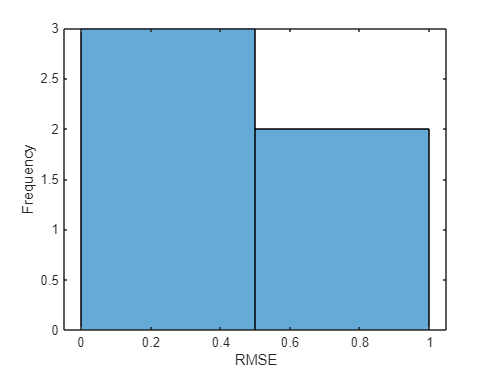


figure
histogram(err)
xlabel("RMSE")
ylabel("Frequency")


Error = mean(err,"all")

Error = single
0.4001

Error2 = mean(err2)

Error2 = single
1.7019

## Forecast Future Time Steps

for idx =1:5
% idx = 3;
X = TeWellpred{idx};
T = TeWelltar{idx};

figure
stackedplot(X(:,7:9),DisplayLabels= ["Oil" "Gas" "Water"])
xlabel("Time Step")
title("Well" + idx)


### Open Loop Forecasting

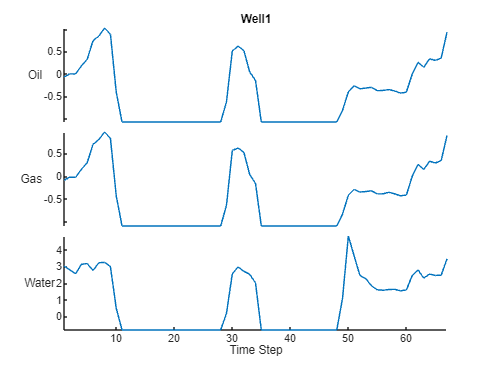

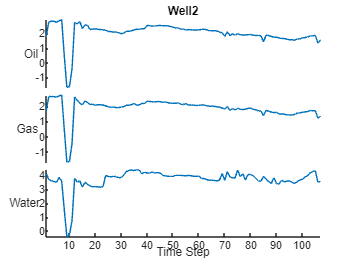

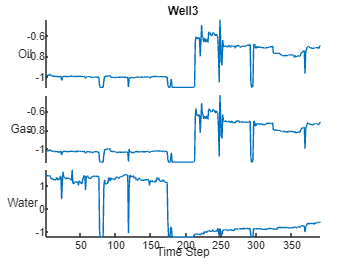

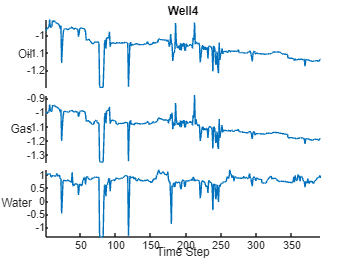

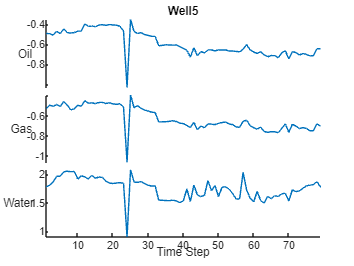

T1net = resetState(T1net);
offset = 50;
[Z,state] = predict(T1net,X(1:offset,:));
T1net.State = state;

Forecast

numTimeSteps = size(X,1);
numPredictionTimeSteps = numTimeSteps - offset;
Y = zeros(numPredictionTimeSteps,3);
Y(1,:) = Z(end,:);

for t = 1:numPredictionTimeSteps-1
    Xt = X(offset+t,:);
    [Y(t+1,:),state] = predict(T1net,Xt);
    T1net.State = state;
end


Compare the predictions with the input values.

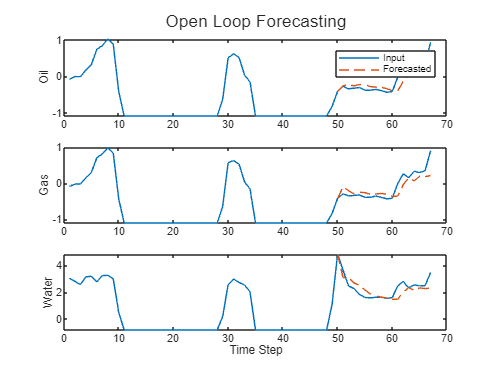

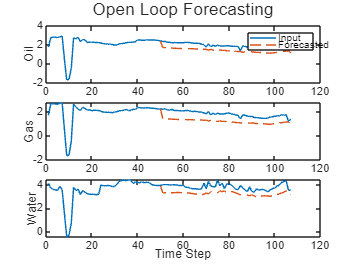

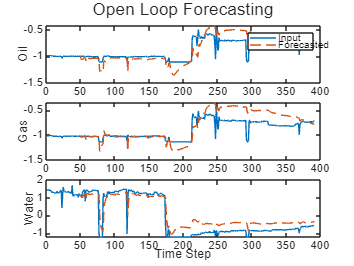

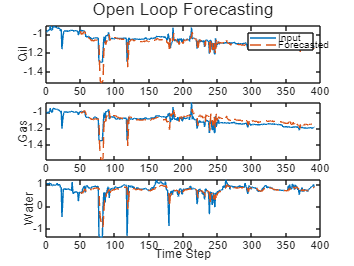

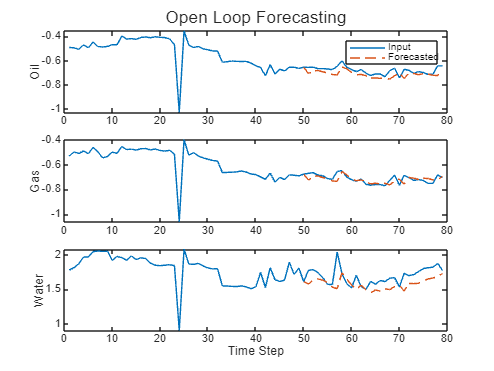

figure
t = tiledlayout(3,1);
title(t,"Open Loop Forecasting")
Lab = ["Oil" "Gas" "Water"];
for i = 1:3
    nexttile
    plot(X(:,6+i))
    hold on
    plot(offset:numTimeSteps,[X(offset,6+i) Y(:,i)'],"--")
    ylabel(Lab(i))
end

xlabel("Time Step")
nexttile(1)
legend(["Input" "Forecasted"])


### Closed Loop Forecasting

T1net = resetState(T1net);
% offset = size(X,1);
offset = 50;
[Z,state] = predict(T1net,X(1:offset,:));
T1net.State = state;


Forecast

numPredictionTimeSteps = 15;
Y = zeros(numPredictionTimeSteps,3);
Y(1,:) = Z(end,:);

for t = 1:numPredictionTimeSteps-1
    [Y(t+1,:),state] = predict(T1net,[X(offset-1+t,1:6) Y(t,:)]);
    net.State = state;
end


Visualize Forecast

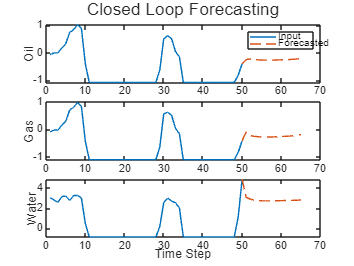

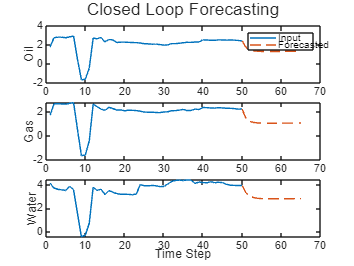

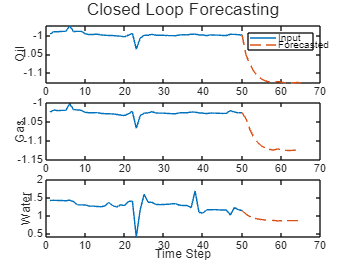

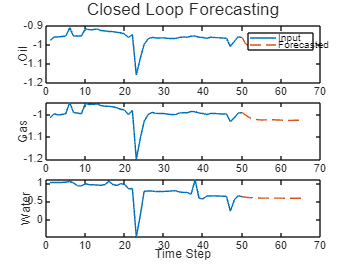

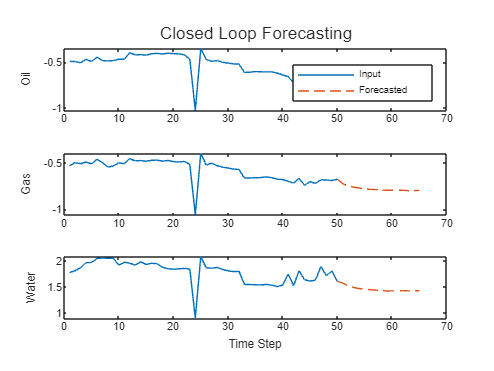

numTimeSteps = offset + numPredictionTimeSteps;

figure
t = tiledlayout(3,1);
title(t,"Closed Loop Forecasting")

for i = 1:3
    nexttile
    plot(X(1:offset,6+i))
    hold on
    plot(offset:numTimeSteps,[X(offset,6+i) Y(:,i)'],"--")
    ylabel(Lab(i))
end

xlabel("Time Step")
nexttile(1)
legend(["Input" "Forecasted"])

end

### Convert Standardize data to Original Data


YT = (Y.*sigT{5}) + muT{5}

YT = 15×3
1.0e+05 *

    0.0076    6.3026    0.0006
    0.0074    6.1903    0.0006
    0.0073    6.1193    0.0006
    0.0073    6.0719    0.0006
    0.0072    6.0273    0.0006
    0.0072    6.0051    0.0006
    0.0072    5.9882    0.0005
    0.0072    5.9685    0.0005
    0.0072    5.9546    0.0005
    0.0072    5.9581    0.0005


### Prepare Forecast Data

Vwell = cell(5,1);
for k = 1:5
    iv = ValidationData{:,4} == 104+k;
    Vwell{k} = ValidationData(iv,:);
    %Extract Predictors
    Vwell{k} = Vwell{k}(:,8:16);
    Vwell{k} = Vwell{k}{:,:};
    %normalize
    Vwell{k} = (Vwell{k} - mux{k}(:,1:end)) ./ sigx{k}(:,1:end);
    miss = nnz(ismissing(Vwell{k}));
    if miss > 0
     Vwell{k} = fillmissing(Vwell{k},"constant",0);
    end
end



### Forecast Validation Data

H = 5×1 cell array
    { 382×9 double}
    { 612×9 double}
    {2219×9 double}
    {2219×9 double}
    { 453×9 double}


U = 5×1 cell array
    { 68×9 double}
    {108×9 double}
    {392×9 double}
    {392×9 double}
    { 80×9 double}


W = 450×9
   -6.3340   -9.2671   -4.4313         0   -1.8807   -1.2263   -1.0826   -1.1062   -0.8289
   -6.3340   -9.2671   -4.4313         0   -1.8807   -1.2263   -1.0826   -1.1062   -0.8289
   -6.3340   -9.2671   -4.4313         0   -1.8807   -1.2263   -1.0826   -1.1062   -0.8289
   -6.3340   -9.2671   -4.4313         0   -1.8807   -1.2263   -1.0826   -1.1062   -0.8289
    1.9439   -0.7020    2.1044         0   -0.6229    0.2366   -1.0826   -1.1062   -0.8289
    1.7606   -0.6978    2.2026         0   -1.0426   -0.2508   -1.0826   -1.1062   -0.8289
    1.7615   -0.6947    2.0750         0   -0.8355   -0.5113   -1.0826   -1.1062   -0.8289
    1.7681   -0.6938    2.2342         0   -1.0828   -0.3090   -1.0826   -1.1062   -0.8289
    1.7701   -0.6892    2.4028         0   -1.3518   -0.6874   -1.0826   -1.1062   -0.8289
    1.7683   -0.6853    2.6322         0   -1.7241   -1.1603   -1.0826   -1.1062   -0.8289


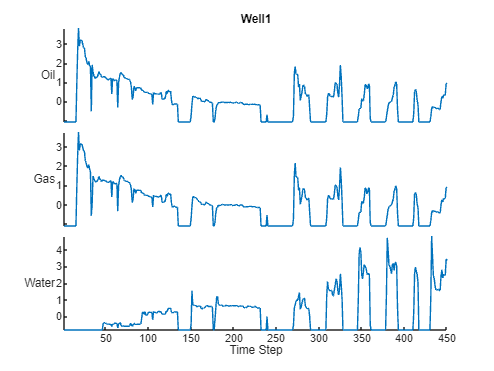

M = 746×9
   -6.3340   -9.2671   -4.4313         0   -1.8807   -1.2263   -1.0826   -1.1062   -0.8289
   -6.3340   -9.2671   -4.4313         0   -1.8807   -1.2263   -1.0826   -1.1062   -0.8289
   -6.3340   -9.2671   -4.4313         0   -1.8807   -1.2263   -1.0826   -1.1062   -0.8289
   -6.3340   -9.2671   -4.4313         0   -1.8807   -1.2263   -1.0826   -1.1062   -0.8289
    1.9439   -0.7020    2.1044         0   -0.6229    0.2366   -1.0826   -1.1062   -0.8289
    1.7606   -0.6978    2.2026         0   -1.0426   -0.2508   -1.0826   -1.1062   -0.8289
    1.7615   -0.6947    2.0750         0   -0.8355   -0.5113   -1.0826   -1.1062   -0.8289
    1.7681   -0.6938    2.2342         0   -1.0828   -0.3090   -1.0826   -1.1062   -0.8289
    1.7701   -0.6892    2.4028         0   -1.3518   -0.6874   -1.0826   -1.1062   -0.8289
    1.7683   -0.6853    2.6322         0   -1.7241   -1.1603   -1.0826   -1.1062   -0.8289


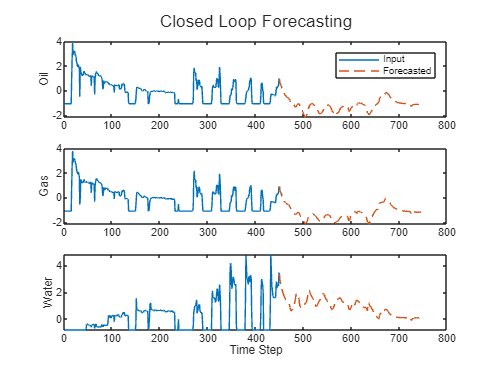

H = 5×1 cell array
    { 382×9 double}
    { 612×9 double}
    {2219×9 double}
    {2219×9 double}
    { 453×9 double}


U = 5×1 cell array
    { 68×9 double}
    {108×9 double}
    {392×9 double}
    {392×9 double}
    { 80×9 double}


W = 720×9
   -4.5989   -5.1456   -4.4594   -2.5686   -3.1328   -2.2635   -2.5617   -2.5993   -1.2720
   -4.5989   -5.1456   -4.4594   -2.5686   -3.1328   -2.2635   -2.5617   -2.5993   -1.2720
   -4.5989   -5.1456   -4.4594   -2.5686   -3.1328   -2.2635   -2.5617   -2.5993   -1.2720
   -4.5989   -5.1456   -4.4594   -2.5686   -3.1328   -2.2635   -2.5617   -2.5993   -1.2720
   -4.5989   -5.1456   -4.4594   -2.5686   -3.1328   -2.2635   -2.5617   -2.5993   -1.2720
   -4.5989   -5.1456   -4.4594   -2.5686   -3.1328   -2.2635   -2.5617   -2.5993   -1.2720
   -4.5989   -5.1456   -4.4594   -2.5686   -3.1328   -2.2635   -2.5617   -2.5993   -1.2720
   -4.5989   -5.1456   -4.4594   -2.5686   -3.1328   -2.2635   -2.5617   -2.5993   -1.2720
   -4.5989   -5.1456   -4.4594   -2.5686   -3.1328   -2.2635   -2.5617   -2.5993   -1.2720
   -4.5989   -5.1456   -4.4594   -2.5686   -3.1328   -2.2635   -2.5617   -2.5993   -1.2720


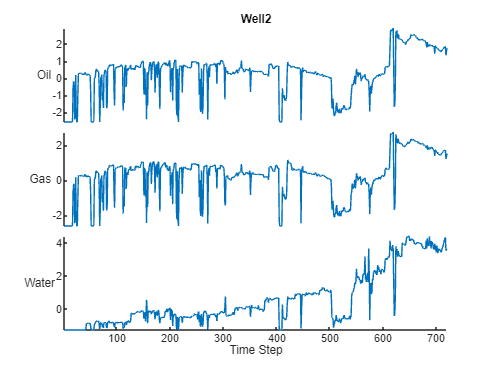

M = 1165×9
   -4.5989   -5.1456   -4.4594   -2.5686   -3.1328   -2.2635   -2.5617   -2.5993   -1.2720
   -4.5989   -5.1456   -4.4594   -2.5686   -3.1328   -2.2635   -2.5617   -2.5993   -1.2720
   -4.5989   -5.1456   -4.4594   -2.5686   -3.1328   -2.2635   -2.5617   -2.5993   -1.2720
   -4.5989   -5.1456   -4.4594   -2.5686   -3.1328   -2.2635   -2.5617   -2.5993   -1.2720
   -4.5989   -5.1456   -4.4594   -2.5686   -3.1328   -2.2635   -2.5617   -2.5993   -1.2720
   -4.5989   -5.1456   -4.4594   -2.5686   -3.1328   -2.2635   -2.5617   -2.5993   -1.2720
   -4.5989   -5.1456   -4.4594   -2.5686   -3.1328   -2.2635   -2.5617   -2.5993   -1.2720
   -4.5989   -5.1456   -4.4594   -2.5686   -3.1328   -2.2635   -2.5617   -2.5993   -1.2720
   -4.5989   -5.1456   -4.4594   -2.5686   -3.1328   -2.2635   -2.5617   -2.5993   -1.2720
   -4.5989   -5.1456   -4.4594   -2.5686   -3.1328   -2.2635   -2.5617   -2.5993   -1.2720


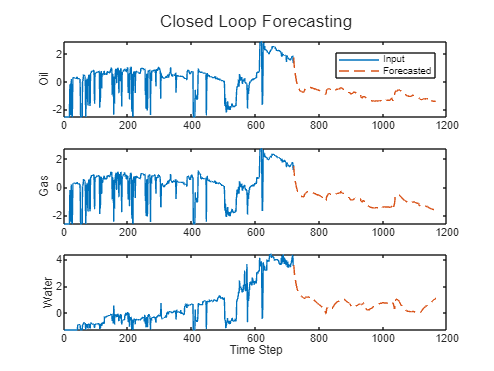

H = 5×1 cell array
    { 382×9 double}
    { 612×9 double}
    {2219×9 double}
    {2219×9 double}
    { 453×9 double}


U = 5×1 cell array
    { 68×9 double}
    {108×9 double}
    {392×9 double}
    {392×9 double}
    { 80×9 double}


W = 2611×9
    1.5354    1.1125    1.2901    0.3635    2.3756    3.1533   -0.9425   -0.9833   -1.0186
    1.4963    1.1312    1.0400    0.0292    2.9888    3.0245   -0.0395    0.0133   -1.2067
    1.4382    1.1383    1.0363   -0.5564    2.6766    2.5957    0.6751    0.9224   -1.2097
    1.4544    1.1378    1.0228   -1.6941    2.8121    2.7821    0.3812    0.4105   -1.2098
    1.4410    1.1390    1.0184   -0.5987    2.7513    2.6967    0.6339    0.5523   -1.2079
    1.4380    1.1393    1.0164   -0.2911    2.7414    2.6881    0.5945    0.5697   -1.2094
    1.4275    1.1400    1.0241   -0.0456    2.6576    2.6021    0.5933    0.5336   -1.2071
    1.4245    1.1400    1.0127    0.3899    2.6788    2.6478    0.6307    0.5958   -1.2099
    1.4186    1.1402    1.0075    0.5329    2.6627    2.6252    0.6370    0.6515   -1.2101
    1.4145    1.1403    1.0045    0.4853    2.6499    2.5891    0.6217    0.5739   -1.2101


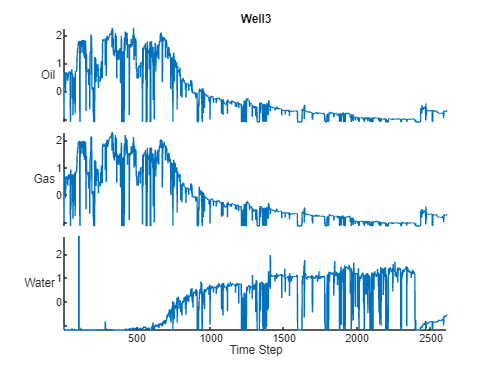

M = 3056×9
    1.5354    1.1125    1.2901    0.3635    2.3756    3.1533   -0.9425   -0.9833   -1.0186
    1.4963    1.1312    1.0400    0.0292    2.9888    3.0245   -0.0395    0.0133   -1.2067
    1.4382    1.1383    1.0363   -0.5564    2.6766    2.5957    0.6751    0.9224   -1.2097
    1.4544    1.1378    1.0228   -1.6941    2.8121    2.7821    0.3812    0.4105   -1.2098
    1.4410    1.1390    1.0184   -0.5987    2.7513    2.6967    0.6339    0.5523   -1.2079
    1.4380    1.1393    1.0164   -0.2911    2.7414    2.6881    0.5945    0.5697   -1.2094
    1.4275    1.1400    1.0241   -0.0456    2.6576    2.6021    0.5933    0.5336   -1.2071
    1.4245    1.1400    1.0127    0.3899    2.6788    2.6478    0.6307    0.5958   -1.2099
    1.4186    1.1402    1.0075    0.5329    2.6627    2.6252    0.6370    0.6515   -1.2101
    1.4145    1.1403    1.0045    0.4853    2.6499    2.5891    0.6217    0.5739   -1.2101


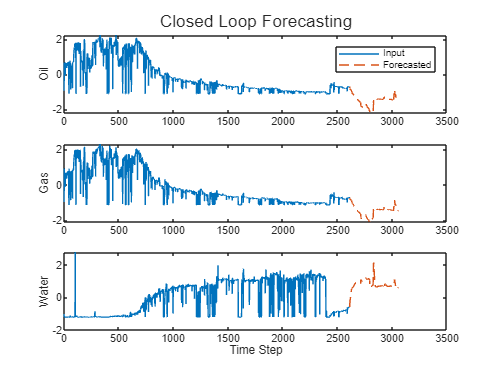

H = 5×1 cell array
    { 382×9 double}
    { 612×9 double}
    {2219×9 double}
    {2219×9 double}
    { 453×9 double}


U = 5×1 cell array
    { 68×9 double}
    {108×9 double}
    {392×9 double}
    {392×9 double}
    { 80×9 double}


W = 2611×9
   -3.4464   -3.5171   -3.2427   -0.6211   -1.8797   -0.9304   -1.2987   -1.3516   -1.3614
   -3.4464   -3.5171   -3.2427   -0.6211   -1.8797   -0.9300   -1.2987   -1.3516   -1.3614
   -3.4464   -3.5171   -3.2427   -0.6211   -1.8797   -0.9308   -1.2987   -1.3516   -1.3614
   -3.4464   -3.5171   -3.2427   -0.6211   -1.8797   -0.9301   -1.2987   -1.3516   -1.3614
   -3.4464   -3.5171   -3.2427   -0.6211   -1.8797   -0.9283   -1.2987   -1.3516   -1.3614
   -3.4464   -3.5171   -3.2427   -0.6211   -1.8797   -0.9268   -1.2987   -1.3516   -1.3614
   -3.4464   -3.5171   -3.2427   -0.6211   -1.8797   -0.9223   -1.2987   -1.3516   -1.3614
   -3.4464   -3.5171   -3.2427   -0.6211   -1.8797   -0.9069   -1.2987   -1.3516   -1.3614
   -3.4464   -3.5171   -3.2427   -0.6211   -1.8797   -0.9047   -1.2987   -1.3516   -1.3614
   -3.4464   -3.5171   -3.2427   -0.6211   -1.8797   -0.8988   -1.2987   -1.3516   -1.3614


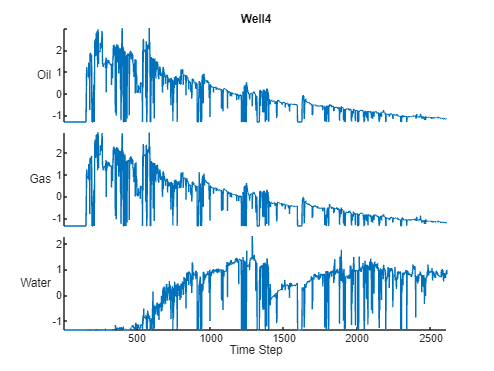

M = 3056×9
   -3.4464   -3.5171   -3.2427   -0.6211   -1.8797   -0.9304   -1.2987   -1.3516   -1.3614
   -3.4464   -3.5171   -3.2427   -0.6211   -1.8797   -0.9300   -1.2987   -1.3516   -1.3614
   -3.4464   -3.5171   -3.2427   -0.6211   -1.8797   -0.9308   -1.2987   -1.3516   -1.3614
   -3.4464   -3.5171   -3.2427   -0.6211   -1.8797   -0.9301   -1.2987   -1.3516   -1.3614
   -3.4464   -3.5171   -3.2427   -0.6211   -1.8797   -0.9283   -1.2987   -1.3516   -1.3614
   -3.4464   -3.5171   -3.2427   -0.6211   -1.8797   -0.9268   -1.2987   -1.3516   -1.3614
   -3.4464   -3.5171   -3.2427   -0.6211   -1.8797   -0.9223   -1.2987   -1.3516   -1.3614
   -3.4464   -3.5171   -3.2427   -0.6211   -1.8797   -0.9069   -1.2987   -1.3516   -1.3614
   -3.4464   -3.5171   -3.2427   -0.6211   -1.8797   -0.9047   -1.2987   -1.3516   -1.3614
   -3.4464   -3.5171   -3.2427   -0.6211   -1.8797   -0.8988   -1.2987   -1.3516   -1.3614


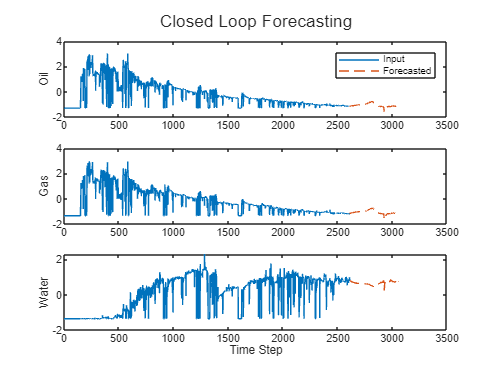

H = 5×1 cell array
    { 382×9 double}
    { 612×9 double}
    {2219×9 double}
    {2219×9 double}
    { 453×9 double}


U = 5×1 cell array
    { 68×9 double}
    {108×9 double}
    {392×9 double}
    {392×9 double}
    { 80×9 double}


W = 533×9
    3.3272   -4.6810    7.0683   -2.9820   -1.3867    0.0561   -1.9754   -1.9975   -0.6757
    3.3347   -4.6600    6.9001   -2.9820   -1.2300    0.2145   -1.9754   -1.9975   -0.6757
    3.3138   -4.6226    6.9792   -2.9820   -1.3283    0.1149   -1.9754   -1.9975   -0.6757
    3.3509   -5.0669    6.4164   -2.8715   -0.7871    0.4178   -1.9754   -1.9975   -0.6757
    1.0946   -0.6867    1.2854    0.6113    0.4464    0.4632    1.7465    1.7563   -0.6757
    0.0889    0.2115   -0.1176    0.7639    0.2288    0.1707    3.1703    3.1651   -0.6757
   -0.1718    0.2647   -0.3716    2.2626    0.0773    0.0412    3.4648    3.5622   -0.6757
   -0.2994    0.2757   -0.4554    1.8682   -0.0319   -0.0533    3.2997    3.2274   -0.6757
   -0.2667    0.2271   -0.4199   -0.7144   -0.0163   -0.0371    3.0033    2.8170   -0.6757
   -0.3537    0.2386   -0.5027   -0.7739   -0.0684   -0.0894    3.1040    2.8832   -0.6757


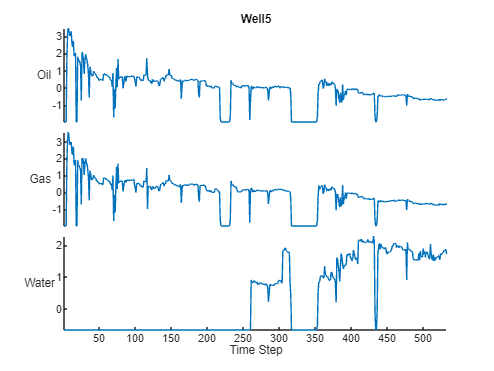

M = 977×9
    3.3272   -4.6810    7.0683   -2.9820   -1.3867    0.0561   -1.9754   -1.9975   -0.6757
    3.3347   -4.6600    6.9001   -2.9820   -1.2300    0.2145   -1.9754   -1.9975   -0.6757
    3.3138   -4.6226    6.9792   -2.9820   -1.3283    0.1149   -1.9754   -1.9975   -0.6757
    3.3509   -5.0669    6.4164   -2.8715   -0.7871    0.4178   -1.9754   -1.9975   -0.6757
    1.0946   -0.6867    1.2854    0.6113    0.4464    0.4632    1.7465    1.7563   -0.6757
    0.0889    0.2115   -0.1176    0.7639    0.2288    0.1707    3.1703    3.1651   -0.6757
   -0.1718    0.2647   -0.3716    2.2626    0.0773    0.0412    3.4648    3.5622   -0.6757
   -0.2994    0.2757   -0.4554    1.8682   -0.0319   -0.0533    3.2997    3.2274   -0.6757
   -0.2667    0.2271   -0.4199   -0.7144   -0.0163   -0.0371    3.0033    2.8170   -0.6757
   -0.3537    0.2386   -0.5027   -0.7739   -0.0684   -0.0894    3.1040    2.8832   -0.6757


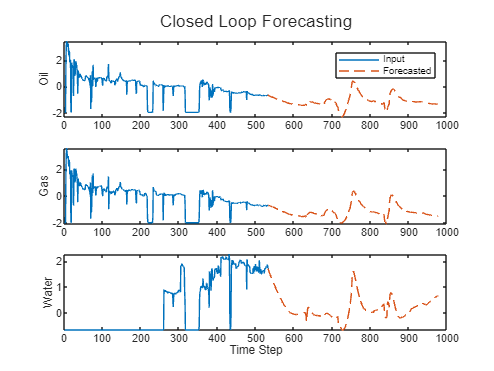

% Xv = cell(5,1);
Yvc = cell(5,1);
Zvc = cell(5,1);
for idx = 1:5
Xv = Vwell{idx};
H = preprocess(Wellpred,mux,sigx)
U = preprocess(s,mux,sigx)
W = [H{idx} ; U{idx}]
% T1 = Vwelltar{idx};

figure
stackedplot(W(:,7:9),DisplayLabels= ["Oil" "Gas" "Water"])
xlabel("Time Step")
title("Well" + idx)

T1net = resetState(T1net);
offset = size(W,1);
[Zv,state] = predict(T1net,W(1:offset,:));
T1net.State = state;

%Forecast
numPredictionTimeSteps = size(Xv,1);
Yv = zeros(numPredictionTimeSteps,3);
Yv(1,:) = Zv(end,:);
M = [W ; Xv]
for t = 1:numPredictionTimeSteps-1
    [Yv(t+1,:),state] = predict(T1net,[M(offset+1-t,1:6) Yv(t,:)]);
    T1net.State = state;
end
    numTimeSteps = offset + numPredictionTimeSteps;

% visualize Forecast
figure
t = tiledlayout(3,1);
title(t,"Closed Loop Forecasting")

for i = 1:3
    nexttile
    plot(M(1:offset,6+i))
    hold on
    plot(offset:numTimeSteps,[M(offset,6+i) Yv(:,i)'],"--")
    ylabel(Lab(i))
end

xlabel("Time Step")
nexttile(1)
legend(["Input" "Forecasted"])


Yvc{idx} = Yv;
Zvc{idx} = Zv;

end

### Convert Forecasted to Original Value

Ypred = cell(5,1);
for k = 1:5
   Ypred{k} = (Yvc{k}.*sigT{k}) + muT{k}; 
end

varnames = ValidationData.Properties.VariableNames;
D = cat(1,Ypred{:})

D = 2075×3
1.0e+06 *

    0.0034    2.7733    0.0054
    0.0032    2.5401    0.0051
    0.0030    2.3691    0.0048
    0.0028    2.2048    0.0046
    0.0026    2.0490    0.0044
    0.0024    1.8933    0.0042
    0.0022    1.7496    0.0041
    0.0020    1.6165    0.0039
    0.0019    1.4743    0.0038
    0.0017    1.3425    0.0036



ValidationData(:,14:16) = array2table(D,"VariableNames",varnames(14:16))

ValidationData = 2075×16 table
      PRODUCTION DATE      Field Name     WELL_BORE_CODE      N_WELL_BORE_CODE    WellBore Name     FLOW_KIND      WELL_TYPE    Downhole Pressure (PSI)    Downhole Temperature (Kelvin)    Average Tubing Pressure    Annulus Pressure (PSI)    AVG WHP (PSI)    Choke Size    Oil Production (stb/day)    Gas Volume (scf/day)    Water Production (stb/day)
    ___________________    __________    _________________    ________________    _____________    ____________    _________    _______________________    _____________________________    

function b = preprocess(b,mux,sigx)
 for k = 1:5
  % TeWellpred{k} = normalize(TeWellpred{k})
  % TeWelltar{k} = normalize(TeWelltar{k})
  b{k} = (b{k} - mux{k}) ./ sigx{k};
  % c{k} = (c{k} - muT{k}) ./ sigT{k};
 % 
  missing = nnz(ismissing(b{k}));
  if missing > 0
     b{k} = fillmissing(b{k},"constant",0); 
  end
 b{k} =  b{k}{:,:};
 
 % c{k} = c{k}{:,:};
 end

end
